# Filtro espectral

clear;
load tseries_test.mat;
[NT,tserie_size] = size(tseries_test);

#### Cargar una serie de tiempo de prueba

Fs = 23;              % Frecuencia de muestra (muestras por unidad de tiempo o espacio)               
T = 1/Fs;             % espacio por muestra    
L = tserie_size;      % Length of signal
t = (0:L-1)*T;        % Time vector

%id = 10;
id =11;
S  = tseries_test(id,:);

#### Agregar huecos de manera artificial aleatoria

% % % %id = 10;
% % % huecos =196;
% % % nhuecos = 0;
% % % Snan = S;
% % % while (nhuecos<huecos)
% % %     x = randi([1 tserie_size]);
% % %     if( ~isnan(Snan(x)) )
% % %         Snan(x)=nan;
% % %         nhuecos=nhuecos+1;
% % %     end
% % % end
% % % 
% % % %%% mostrar la serie original y la serie artifical con huecos
% % % figure;
% % % plot(S);
% % % ylim([0 1]);
% % % xlim([1 tserie_size]);
% % % ylabel('NDVI','FontSize',12);
% % % xlabel('Días','FontSize',12);
% % % hold on; 
% % % plot(Snan);
% % % hold off;
% % % 
% % % mean_snan = mean(Snan,"all","omitnan");
% % % disp("PROMEDIO: "+mean_snan);
% % % Snan( isnan(Snan))=mean_snan;
% % % 
% % % figure;
% % % plot(S);
% % % ylim([0 1]);
% % % xlim([1 tserie_size]);
% % % ylabel('NDVI','FontSize',12);
% % % xlabel('Días','FontSize',12);
% % % hold on; 
% % % plot(Snan);
% % % hold off;


#### Agregar huecos de manera artificial definida

En los años: 2003, 2006, 2008, 2011, 2014, 2015, 2017 2020, 2022

Días: 7, 40, 66, 73, 129, 197, 263, 291, 341, 401, 438

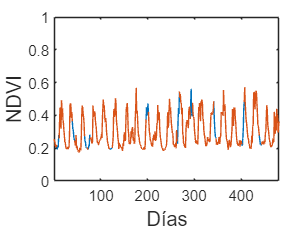

%id = 10;
Snan = S;


tam_huecos =4;
id_huecos= [7 40 66 73 120 197 263 291 341 401 438];
for i=id_huecos
    for j=1:tam_huecos
        Snan(i+j)=nan;
    end
end
Snano = Snan;
for i=id_huecos
    for j=1:tam_huecos
        idp = (i+j):23:tserie_size;
        prom = mean(Snan(idp),"all","omitnan");
        Snan(i+j) = prom;
    end
end



%%% mostrar la serie original y la serie artifical con huecos
figure;
plot(S);
ylim([0 1]);
xlim([1 tserie_size]);
ylabel('NDVI','FontSize',12);
xlabel('Días','FontSize',12);
hold on; 
plot(Snano);
hold off;

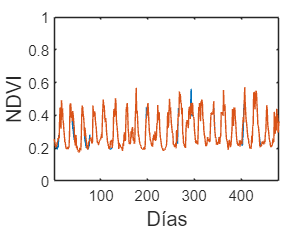


% mean_snan = mean(Snan,"all","omitnan");
% disp("PROMEDIO: "+mean_snan);
% Snan( isnan(Snan))=mean_snan;

figure;
plot(S);
ylim([0 1]);
xlim([1 tserie_size]);
ylabel('NDVI','FontSize',12);
xlabel('Días','FontSize',12);
hold on; 
plot(Snan);
hold off;

## Espectro de amplitud de la serie

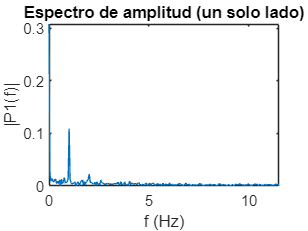

Y = fft(Snan);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
figure;
plot(f,P1) 
title("Espectro de amplitud (un solo lado)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

## Suavizar mediante Frecuencia mayor amplitud

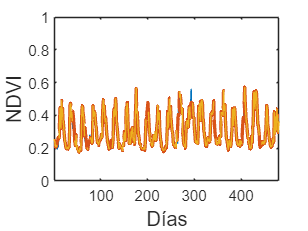

mit = L/2;

rng = 1;
Yf = Y;

Yf(mit-rng+1:mit+rng+1) = 0;
Yfp = abs(Yf);

P2 = abs(Yfp/L);
P1 = P2(1:int16(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

Sf = real(ifft(Yf));
figure;
plot(S);
ylim([0 1]);
xlim([1 tserie_size]);
ylabel('NDVI','FontSize',12);
xlabel('Días','FontSize',12);
hold on
plot(Sf,LineWidth=2);
plot(Snano);
hold off

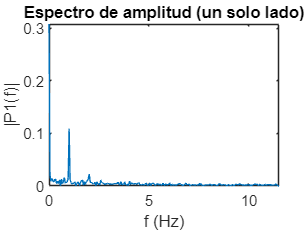


figure;
plot(f,P1) 
title("Espectro de amplitud (un solo lado)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

#### Calcular RMSE MAE CORRELACION Y SESGO



m_rmse = f_rmse(S,Sf)

m_rmse =    0.016126149710046


m_mae = f_mae(S,Sf)

m_mae =    0.006703341912598


cor = corrcoef(S,Sf);
m_corr = cor(2,1)

m_corr =    0.986410230432711



m_sesgo_s = skewness(S)

m_sesgo_s =    0.688619345260873


m_sesgo_sf =skewness(Sf)

m_sesgo_sf =    0.648002275364287



mdl = fitlm(S,Sf);

m_R2o = mdl.Rsquared.Ordinary

m_R2o =    0.973005142702315


m_R2 = mdl.Rsquared.Adjusted

m_R2 =    0.972948668105458
